# (A) p.f. (lagging) = 0.2, 0.4, 0.6 and 0.8 (full load)

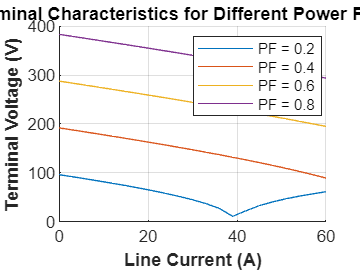


% Initialize parameters
i_a = 0:3:60; % Line current from 0 to 60 A
e_a = 277.0; % Armature voltage
x_s = 1.0; % Synchronous reactance
theta = 36.857 * (pi / 180); % Power factor angle (converted to radians)
power_factors = [0.2, 0.4, 0.6, 0.8]; % Power factors to plot

% Plot characteristics for each power factor
figure;
hold on;
for pf = power_factors
    % Calculate phase voltage for each current level
    v_phase = zeros(1, length(i_a));
    for ii = 1:length(i_a)
        v_phase(ii) = sqrt(abs((e_a * cos(acos(pf)) - (x_s * i_a(ii) * cos(theta)))^2 - (x_s * i_a(ii) * sin(theta))^2));
    end
    % Calculate terminal voltage
    v_t = v_phase * sqrt(3);
    % Plot terminal characteristics
    plot(i_a, v_t, 'DisplayName', sprintf('PF = %.1f', pf));
end

% Customize plot
xlabel('Line Current (A)', 'Fontweight', 'Bold');
ylabel('Terminal Voltage (V)', 'Fontweight', 'Bold');
title('Terminal Characteristics for Different Power Factors', 'Fontweight', 'Bold');
legend('Location', 'best');
grid on;
hold off;

## (A) p.f. (lagging) = 0.2, 0.4, 0.6 and 0.8 (No load)

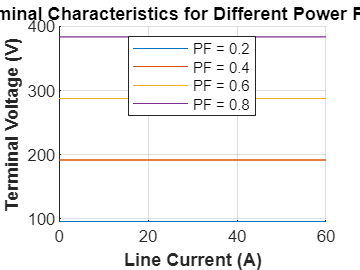

% Initialize parameters
i_a = 0:3:60; % Line current from 0 to 60 A
e_a = 277.0; % Armature voltage
x_s = 1.0; % Synchronous reactance
theta = 36.857 * (pi / 180); % Power factor angle (converted to radians)
power_factors = [0.2, 0.4, 0.6, 0.8]; % Power factors to plot

% Plot characteristics for each power factor
figure;
hold on;
for pf = power_factors
    % Calculate phase voltage for each current level
    v_phase = zeros(1, length(i_a));
    for ii = 1:length(i_a)
        v_phase(ii) = e_a * cos(acos(pf));
    end
    % Calculate terminal voltage
    v_t = v_phase * sqrt(3);
    % Plot terminal characteristics
    plot(i_a, v_t, 'DisplayName', sprintf('PF = %.1f', pf));
end

% Customize plot
xlabel('Line Current (A)', 'Fontweight', 'Bold');
ylabel('Terminal Voltage (V)', 'Fontweight', 'Bold');
title('Terminal Characteristics for Different Power Factors', 'Fontweight', 'Bold');
legend('Location', 'best');
grid on;
hold off;

## (b)p.f. (leading) = 0.2, 0.4, 0.6 and 0.8 (Full load)

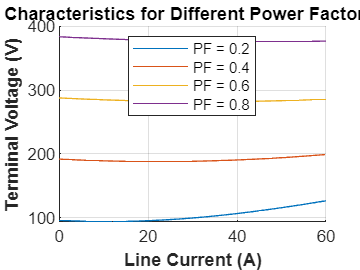

% Initialize parameters
i_a = 0:3:60; % Line current from 0 to 60 A
e_a = 277.0; % Armature voltage
x_s = 1.0; % Synchronous reactance
theta = -acos(0.2); % Power factor angle for leading power factor (converted to radians)
power_factors = [0.2, 0.4, 0.6, 0.8]; % Power factors to plot

% Plot characteristics for each power factor
figure;
hold on;
for pf = power_factors
    % Calculate phase voltage for each current level
    v_phase = zeros(1, length(i_a));
    for ii = 1:length(i_a)
        v_phase(ii) = sqrt(abs((e_a * cos(acos(pf)) - (x_s * i_a(ii) * cos(theta)))^2 + (x_s * i_a(ii) * sin(theta))^2));
    end
    % Calculate terminal voltage
    v_t = v_phase * sqrt(3);
    % Plot terminal characteristics
    plot(i_a, v_t, 'DisplayName', sprintf('PF = %.1f', pf));
end

% Customize plot
xlabel('Line Current (A)', 'Fontweight', 'Bold');
ylabel('Terminal Voltage (V)', 'Fontweight', 'Bold');
title('Terminal Characteristics for Different Power Factors (Leading)', 'Fontweight', 'Bold');
legend('Location', 'best');
grid on;
hold off;

## (b)p.f. (leading) = 0.2, 0.4, 0.6 and 0.8 (No load)

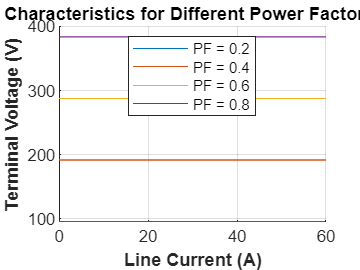

% Initialize parameters
i_a = 0:3:60; % Line current from 0 to 60 A
e_a = 277.0; % Armature voltage
x_s = 1.0; % Synchronous reactance
theta = -acos(0.2); % Power factor angle for leading power factor (converted to radians)
power_factors = [0.2, 0.4, 0.6, 0.8]; % Power factors to plot

% Plot characteristics for each power factor
figure;
hold on;
for pf = power_factors
    % Calculate phase voltage for each current level
    v_phase = zeros(1, length(i_a));
    for ii = 1:length(i_a)
        v_phase(ii) = e_a * cos(acos(pf));
    end
    % Calculate terminal voltage
    v_t = v_phase * sqrt(3);
    % Plot terminal characteristics
    plot(i_a, v_t, 'DisplayName', sprintf('PF = %.1f', pf));
end

% Customize plot
xlabel('Line Current (A)', 'Fontweight', 'Bold');
ylabel('Terminal Voltage (V)', 'Fontweight', 'Bold');
title('Terminal Characteristics for Different Power Factors (Leading)', 'Fontweight', 'Bold');
legend('Location', 'best');
grid on;
hold off;